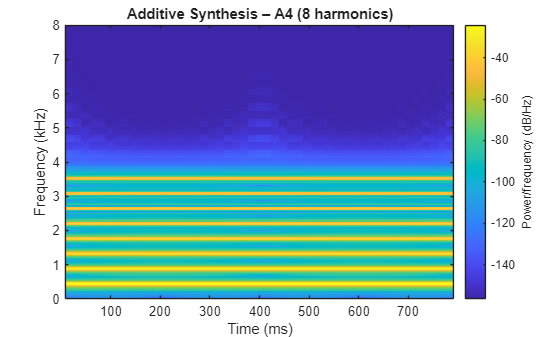

%% Baseline Additive and FM Synthesis Demo – ELEC5305 Project

fs = 16000;      % Sampling rate
dur = 0.8;       % Duration in seconds
fc  = 440;       % Fundamental frequency (A4 note)

%% --- Additive Synthesis ---
t = (0:1/fs:dur-1/fs).';
harmonics = 8;
amps = 1./(1:harmonics);  % Decreasing amplitude
x_add = zeros(size(t));

for k = 1:harmonics
    x_add = x_add + amps(k) * sin(2*pi*k*fc*t);
end
x_add = x_add / max(abs(x_add));

audiowrite('results/audio/additive_A4.wav', x_add, fs);

figure;
spectrogram(x_add, hann(512), 256, 1024, fs, 'yaxis');
title('Additive Synthesis – A4 (8 harmonics)');
saveas(gcf, 'results/plots/additive_A4_spec.png');

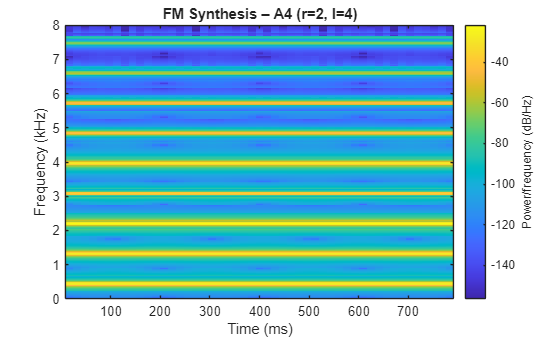


%% --- FM Synthesis ---
r = 2;  % frequency ratio
I = 4;  % modulation index
fm = r * fc;
x_fm = sin(2*pi*fc*t + I*sin(2*pi*fm*t));
x_fm = x_fm / max(abs(x_fm));

audiowrite('results/audio/fm_A4_r2_I4.wav', x_fm, fs);

figure;
spectrogram(x_fm, hann(512), 256, 1024, fs, 'yaxis');
title('FM Synthesis – A4 (r=2, I=4)');
saveas(gcf, 'results/plots/fm_A4_r2_I4_spec.png');